# Week 10 Exercise 3

clear

% Duration (Time) s
T  = 0.5;

% Sampling frequency Hz = 1/s
fs = 2^(13);

% Time vector
t = 0:1/fs:T;


Part a

pure.harmonics = [1 0.6 0.2];
pure.envelope = @(t) 1;

midA.octave = 0;
midA.semitone = 'A';
midA.duration = 0.5;

Part b

w = tone(fs,midA,pure);
W = fft(w/length(w));

Part c

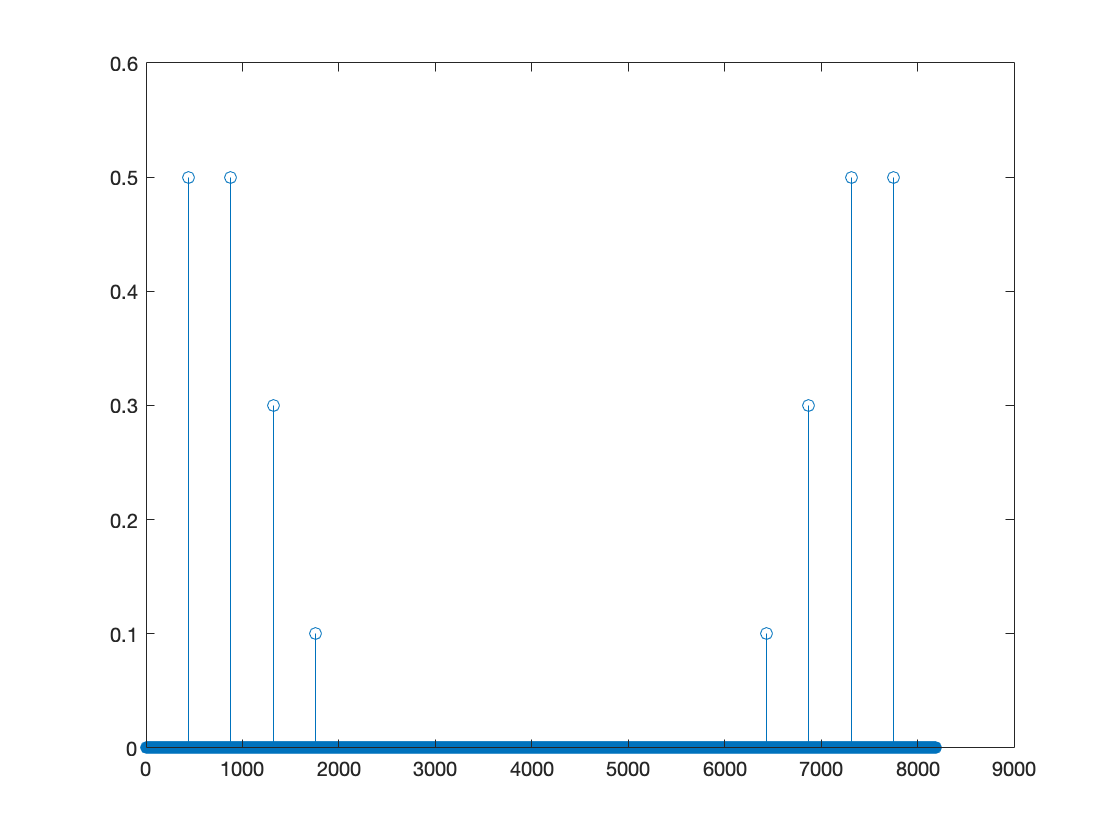

freq = 0:1/T:fs-1/T;
stem(freq, abs(W))

fs-440

ans = 7752

% There are 4 frequency lines that a mirrored at f and fmax-f. This makes
% sense because we added three harmonics to the original note

Part d

midE.octave = 0;
midE.semitone = 'E';
midE.duration = 0.5;

w = tone(fs,midE,pure);
W = fft(w/length(w));
stem(freq, abs(W))
% The results for the middle E are not as clean as those for the middle A
% because the approximation is not as accurate for the specific frequency
% of E.

Part f

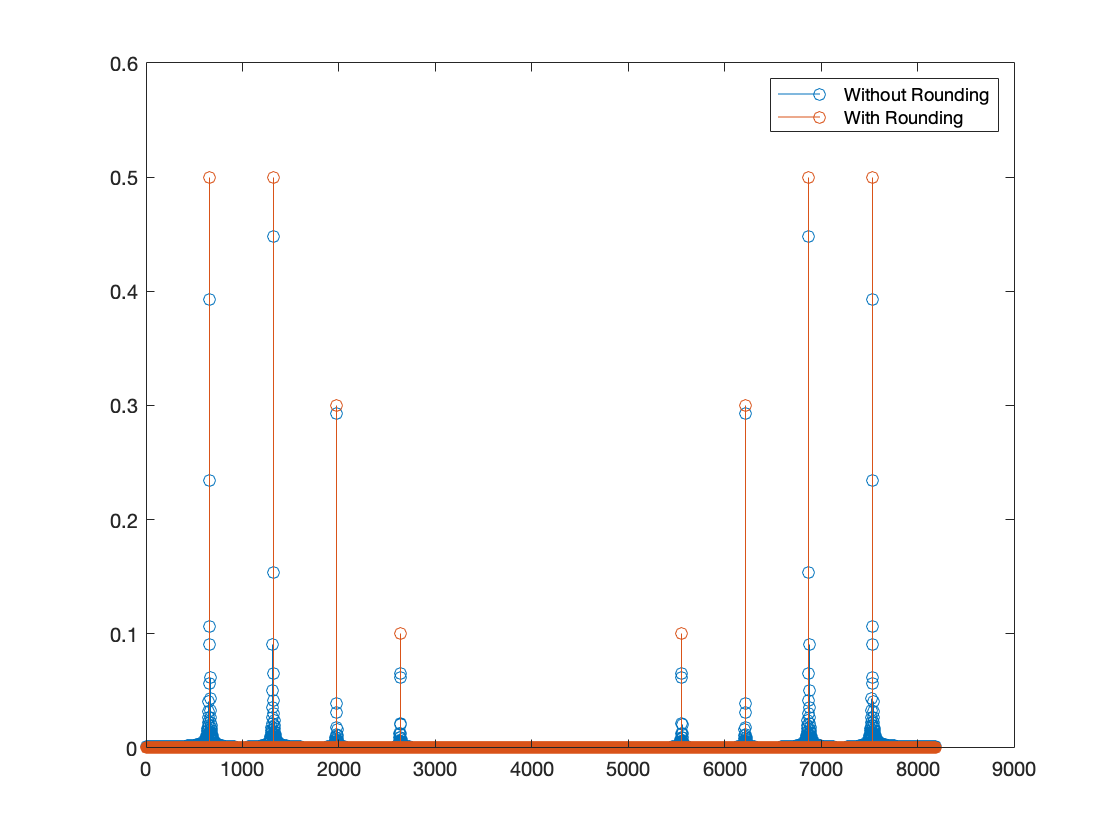

hold on
w = toneF(fs,midE,pure);
W = fft(w/length(w));

stem(freq, abs(W))

legend("Without Rounding", "With Rounding")
hold off

Part g

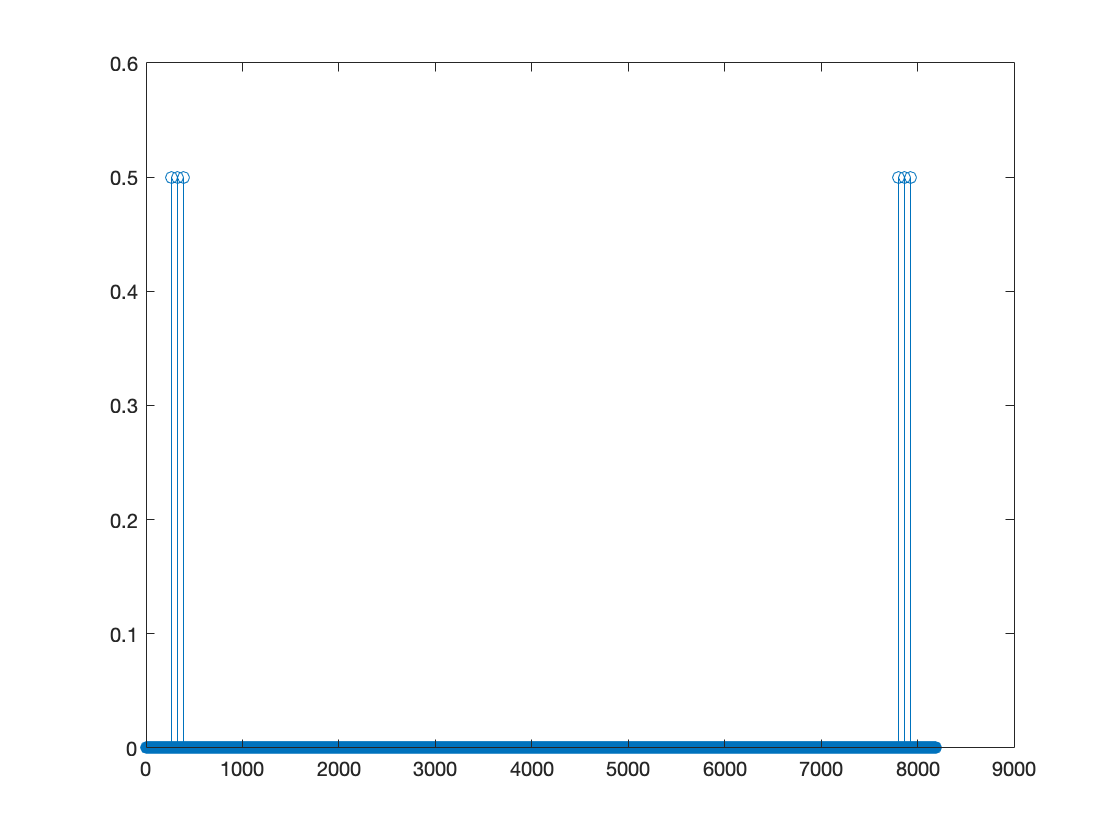

mary2

w = toneF(fs,script(2));
W = fft(w/length(w));
stem(freq, abs(W))